## 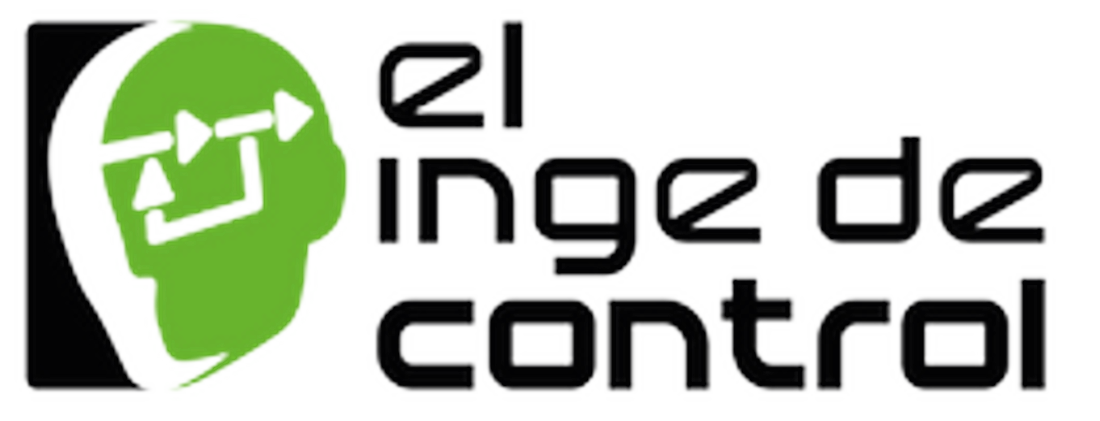

# **Taller: Control Robusto y Estocástico**

## Tema: Control ${\mathcal{H}}_{\infty }$de información completa

## Dr. Julio A. García Rodríguez

Ejercicio 01. $\mathcal{H}_2$

clc, clear all, close all

Set random seed for reproducibility

rng(5, 'twister');

Generate a random state-space system and transpose it. This command creates a 4-output, 5-input stable model and then takes its Hermitian conjugate. This operation yields a 5-output, 4-input unstable model

P = rss(3, 4, 5)';  % 3 states, 5 inputs, 4 outputs → transposed: 4 inputs, 5 outputs
pole(P)             % Confirm that P is unstable. All the poles are in the right half-plane.

ans =     2.8712
    0.2183
    0.2566


Display state-space matrices

A = P.A

A =    -0.1267   -3.4491   -3.9850
    0.5443    5.7729    6.3519
   -0.2139   -2.2218   -2.3001


B = P.B

B =     1.8883         0   -1.1169   -0.7434
         0    1.6665    0.1026         0
    0.1927   -0.7946         0   -0.5391


C = P.C

C =    -0.1757   -0.3175   -1.1016
         0   -1.7622   -1.9355
    1.5269    0.6787         0
         0   -1.1146         0
    0.9764   -1.5769    0.2041


D = P.D

D =          0   -2.5484         0         0
   -0.3145    1.0669    0.2769         0
    0.1754    0.3630         0         0
    1.6490         0   -1.5309   -0.3912
         0         0         0         0



disp('Matrix A:'); disp(A);

Matrix A:
   -0.1267   -3.4491   -3.9850
    0.5443    5.7729    6.3519
   -0.2139   -2.2218   -2.3001



disp('Matrix B:'); disp(B);

Matrix B:
    1.8883         0   -1.1169   -0.7434
         0    1.6665    0.1026         0
    0.1927   -0.7946         0   -0.5391



disp('Matrix C:'); disp(C);

Matrix C:
   -0.1757   -0.3175   -1.1016
         0   -1.7622   -1.9355
    1.5269    0.6787         0
         0   -1.1146         0
    0.9764   -1.5769    0.2041



disp('Matrix D:'); disp(D);

Matrix D:
         0   -2.5484         0         0
   -0.3145    1.0669    0.2769         0
    0.1754    0.3630         0         0
    1.6490         0   -1.5309   -0.3912
         0         0         0         0



Controllability and observability analysis

ctrbRank = rank(ctrb(A, B))

ctrbRank = 3

obsvRank = rank(obsv(A, C))

obsvRank = 3

Step Response

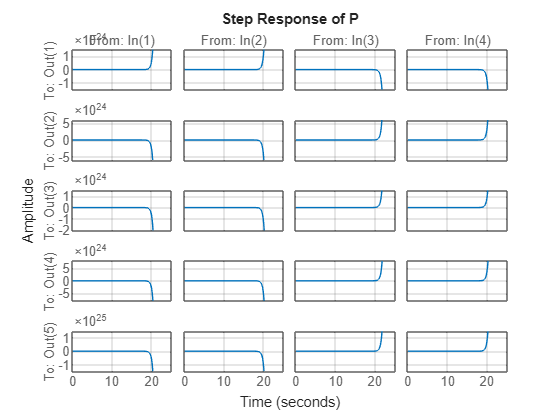

step(P)
title('Step Response of P');
grid on

Impulse response 

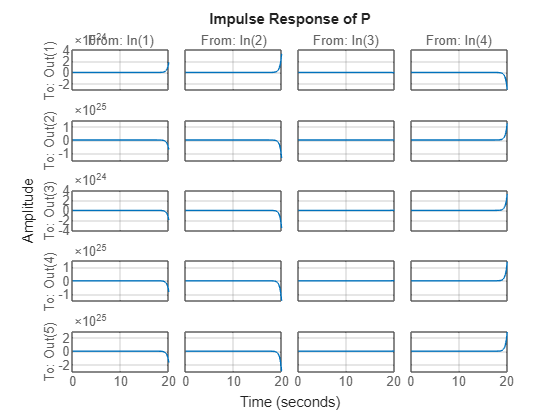

impulse(P)
title('Impulse Response of P');
grid on

Frequency response (Bode plot)

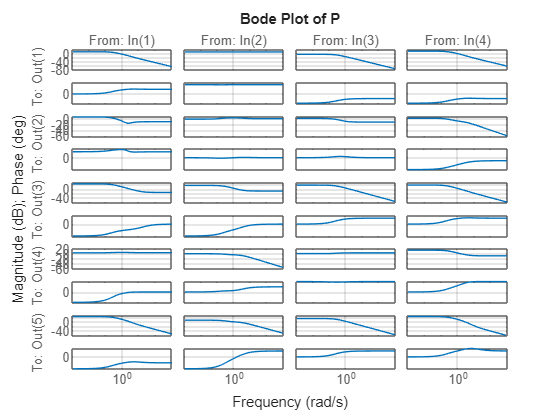

bode(P)
title('Bode Plot of P');
grid on

 Pole-zero map

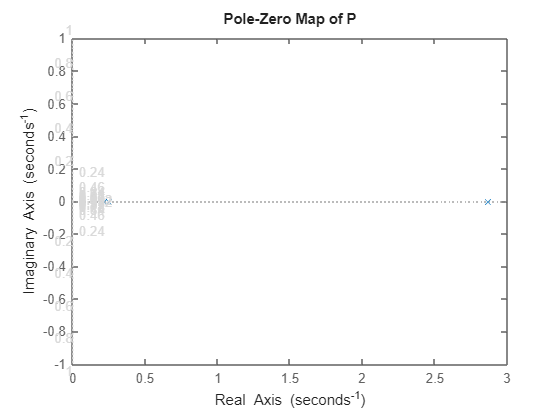

pzmap(P)
title('Pole-Zero Map of P');
grid on

Controller synthesis

[K,CL,GAM] = h2syn(P,2,1);

disp('Controller K:'); disp(K); K

Controller K:
  1×2 ss array with properties:

                A: [3×3 double]
                B: [3×2 double]
                C: [8.8149e+07 4.1672e+07 -9.5290e+07]
                D: [0 0]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {3×1 cell}
        StatePath: {3×1 cell}
        StateUnit: {3×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [2×1 double]
      OutputDelay: 0
        InputName: {2×1 cell}
        InputUnit: {2×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]


K =
 
  A = 
               x1          x2          x3
   x1  -3.927e+07   -4.18e+07    5.68e+07
   x2     8.6e+06  -3.684e+07   1.598e+07
   x3  -4.677e+07  -2.179e+06   3.82

disp('Closed-Loop CL:'); disp(CL);

Closed-Loop CL:
  3×3 ss array with properties:

                A: [6×6 double]
                B: [6×3 double]
                C: [3×6 double]
                D: [3×3 double]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {6×1 cell}
        StatePath: {6×1 cell}
        StateUnit: {6×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [3×1 double]
      OutputDelay: [3×1 double]
        InputName: {3×1 cell}
        InputUnit: {3×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {3×1 cell}
       OutputUnit: {3×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



disp('Gamma:'); disp(GAM);

Gamma:
   Inf

